# ------------------ MIE WRAPPER -----------------

% -----------------------------------------------------------


% This script will run the .INP files using runMIE.m, and then read the .OUT files using readMIE.m.
% The intention of the script is to control the MIE calculation program
% MIE from Matlab. The user will be able to create files, run them and
% view the results here in this live script


clear variables; close all;


% Created by Andrew J. Buggee

## DESIGNATE FOLDER, INPUT AND OUTPUT FILES

% for now, we will manually create uvspec.inp files, and simply call them
% out as variables


% ------- If using macbook -------

folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/',...
    'Hyperspectral-Cloud-Droplet-Retrieval-Research/LibRadTran/',...
    'libRadtran-2.0.4/examples/'];

% ------- If using Mac desktop -------

folderName = '/Users/anbu8374/Documents/LibRadTran/libRadtran-2.0.4/Mie_Calculations/';


inputName = 'Q_ext_for_AVIRIS_monodispersed.INP';


outputName = 'Q_ext_4_AVIRIS_1nm_sampling_monodispersed';







## RUN MIE AND SAVE INPUTS/OUTPUTS

tic
[drop_settings] = runMIE(folderName,inputName,outputName);
toc

Elapsed time is 8.025543 seconds.


## READ UVSPEC OUTPUT FILES

if iscell(outputName)==true

    ds = cell(1,length(outputName));

    for jj = 1:length(outputName)

        [ds{jj},headers,num_radii] = readMIE(folderName,outputName{jj}); % headers don't change per iteration

    end

else

    [ds,headers,num_radii] = readMIE(folderName,outputName);

end





## PLOT AND ANALYZE OUTPUT FILES

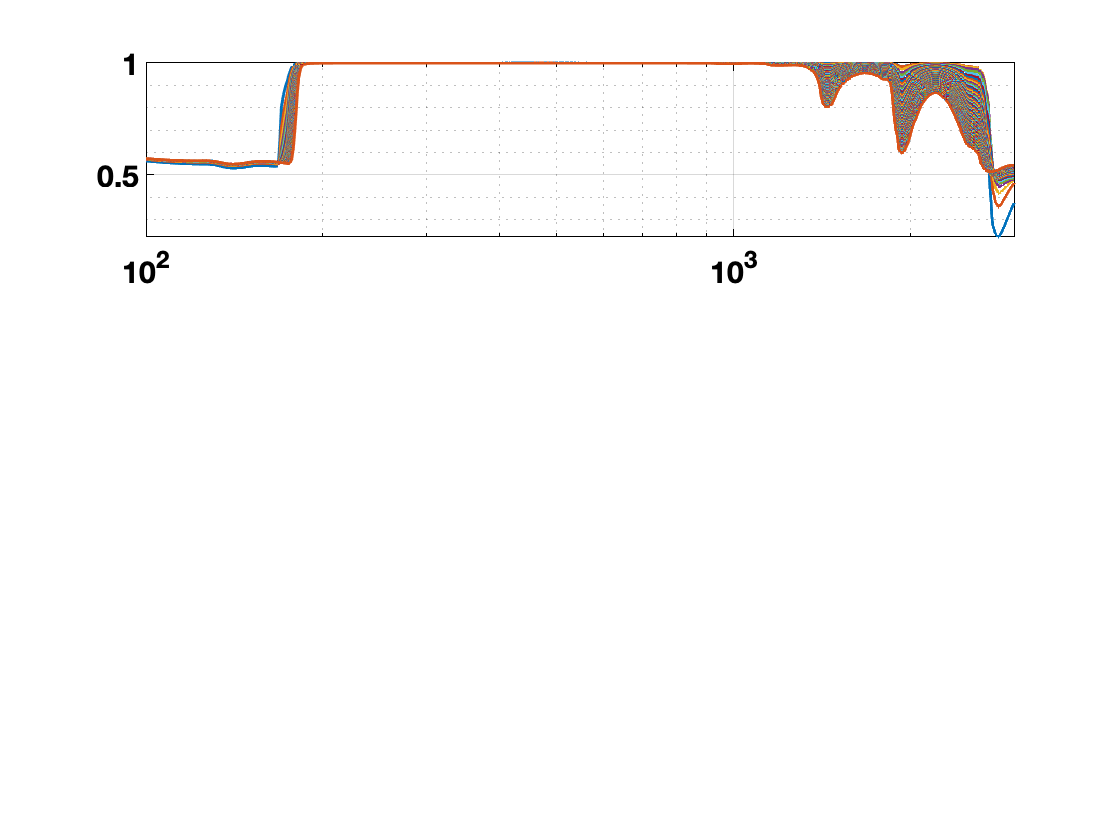

Undefined variable drop_settings.

% Use the following numbers for the desired plot properties
% plotFlag = 1 if livescript plotting is desired
% plotFlag = 2 if black background plots are desired
% plotFlag = 3 if white background plots are desired

plotFlag = 3; % if livescript plotting is deisred

if plotFlag == 1
    liveScriptPlotting;
    
elseif plotFlag == 2
    scriptPlotting_blk;
    
elseif plotFlag == 3
    scriptPlotting_wht;
    
else
    error('Incorrect option for Plot Flag');
end

% First lets plot the Single Scattering, asymmetry and extinction
% coefficient
if iscell(ds)==false

    figure;
    
    subplot(3,1,1)
    p1 = semilogx(ds.wavelength,ds.ssa,'LineWidth',1.5);
    grid on; grid minor
    title(['r_{eff} = ',num2str(drop_settings{1}),', distribution = ',drop_settings{2}])
    ylabel(headers{5})
    %p1.Parent.Position(3) = 1; % this will make the subplots wider by 300 pixels
    % xlim([min(ds.wavelength) max(ds.wavelength)])
    for rr = 1:num_radii
        legend_str{rr} = num2str(drop_settings{1}(rr));
    end
    
    legend(legend_str,'Location',"best")
    
    subplot(3,1,2)
    p2 = semilogx(ds.wavelength,ds.Qext,'LineWidth',1.5);
    grid on; grid minor
    ylabel(headers{4})
    
    subplot(3,1,3)
    p3 = semilogx(ds.wavelength,ds.asymParam,'LineWidth',1.5);
    
    grid on; grid minor
    xlabel(headers{1})
    ylabel(headers{6})

else


end


if plotFlag == 2
    set(gcf,'color','k');
end


## Plot Size Distribution

% if strcmp(drop_settings{2},'log normal')==true
%     r_eff = drop_settings{1};
%     sigma = str2double(drop_settings{3});
%     n_r = a./r * exp(-1/2 * ((log(r) - log(r_eff))./log()))
%     
% elseif strcmp(drop_settings{2},'gamma') == true
%     
%     
% else
%     
% end

% end